# Image Processing

## Steps Taken:-

#### A ) Flattening Image 

- Planefit 0 - along Y

- Flatten 1

- Mask particles

- Unflatten, reflatten 1 with mask 

#### B) Exporting Image

- Set range to 1pm, offset to 0

- Remove all legend, ticks and labels. Set axis color to white

- Set color scale to YellowHot256

- Export in PNG with same resolution

## Cropping background, binarizing image

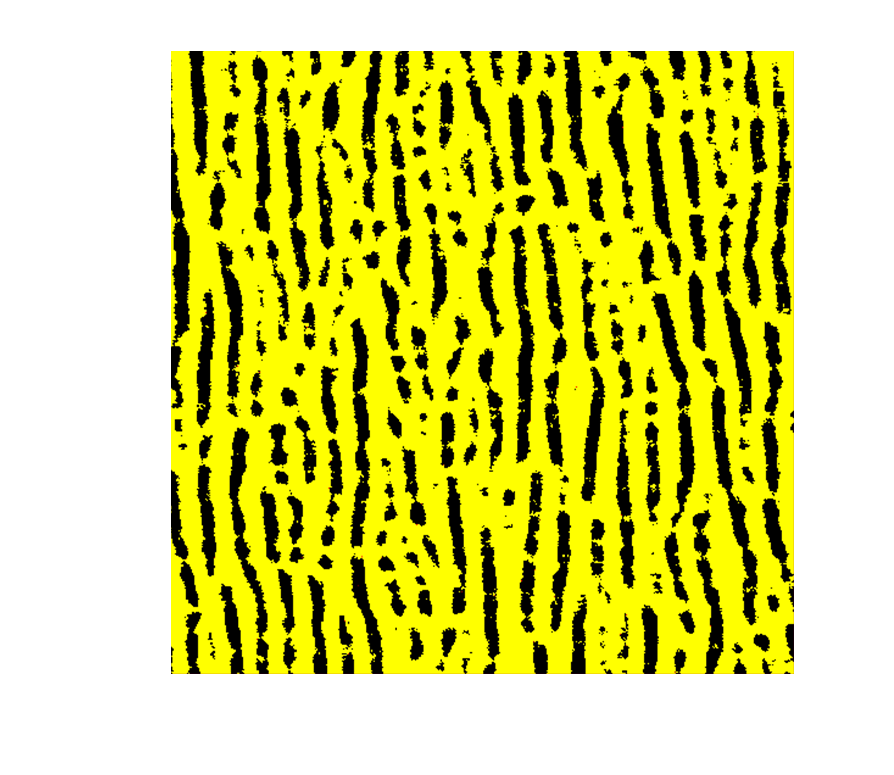

Iorig=imread("D:\Compositionally Graded\Paper_Wr\Paper-1\Data\Euler Analysis\Input_images\PK-197.png");
imshow(Iorig);

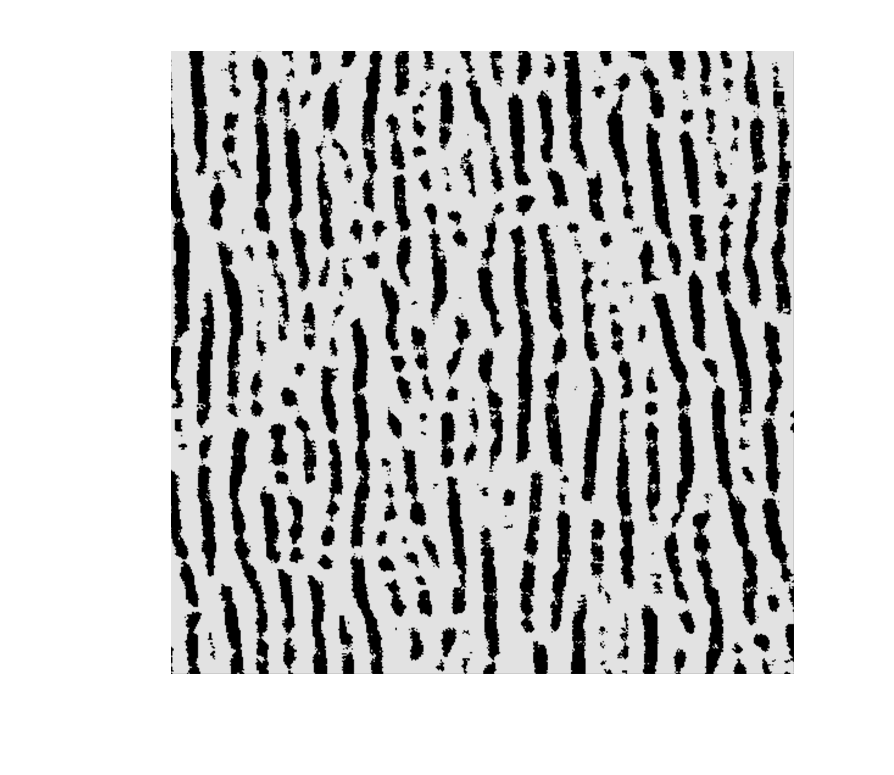

Igray=rgb2gray(Iorig);
imshow(Igray);                       %Igray has c/a phase in gray, a1/a2 in black, and has a white surrounding border

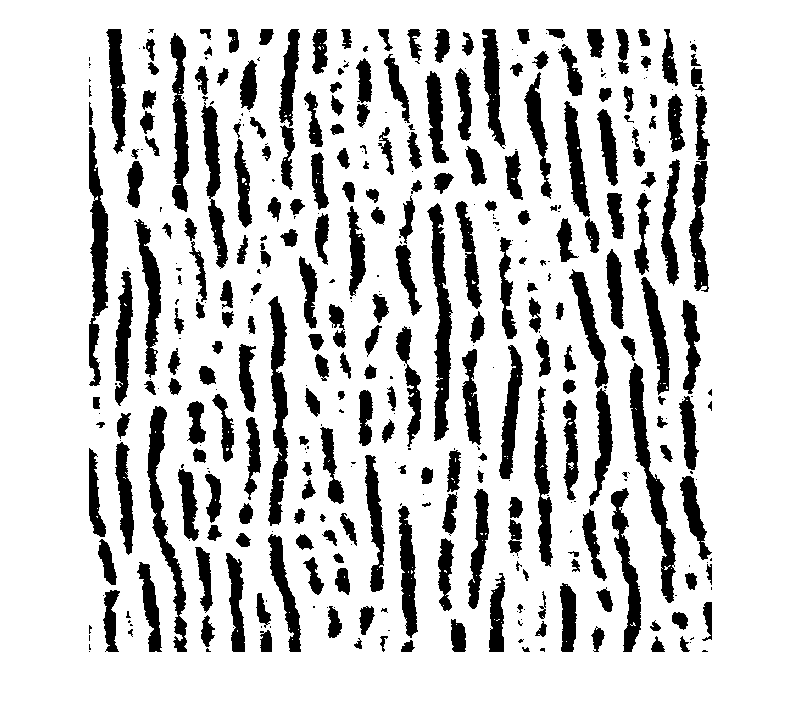

i=1;
while i <=  size(Igray,1)             %While Loop deletes rows which are fully white
    if min(Igray(i,:))== 255
       Igray(i,:)=[];                %Deleting row
       i=i-1;                        %If row is deleted, then count has to be decreased as number of rows has decreased
    end
i=i+1;
end
i=1;
while i <=  size(Igray,2)             %While Loop deletes columns which are fully white    
    if min(Igray(:,i))== 255
       Igray(:,i)=[];                %Deleting column
       i=i-1;                        %If column is deleted, then count has to be decreased as number of columns has decreased
    end
i=i+1;
end
Ibin=imbinarize(Igray);
imshow(Ibin);

## Cleaning up image, removing artifacts

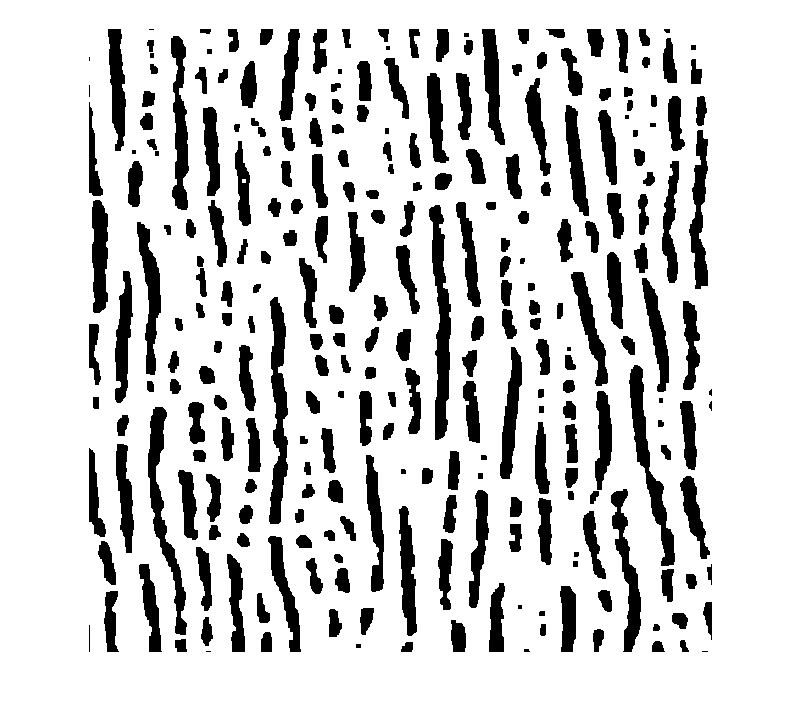

SE=strel('rectangle', [4 4]);        %Structural element for erosion and closing operation
Ieroded=imopen(imclose(Ibin,SE),SE); %Closing to remove small noise due to high gain ringing
Ieroded=imclose(Ieroded,SE);         
imshow(Ieroded);


BW2 = bwperim(Ieroded)

BW2 = 623×623 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0

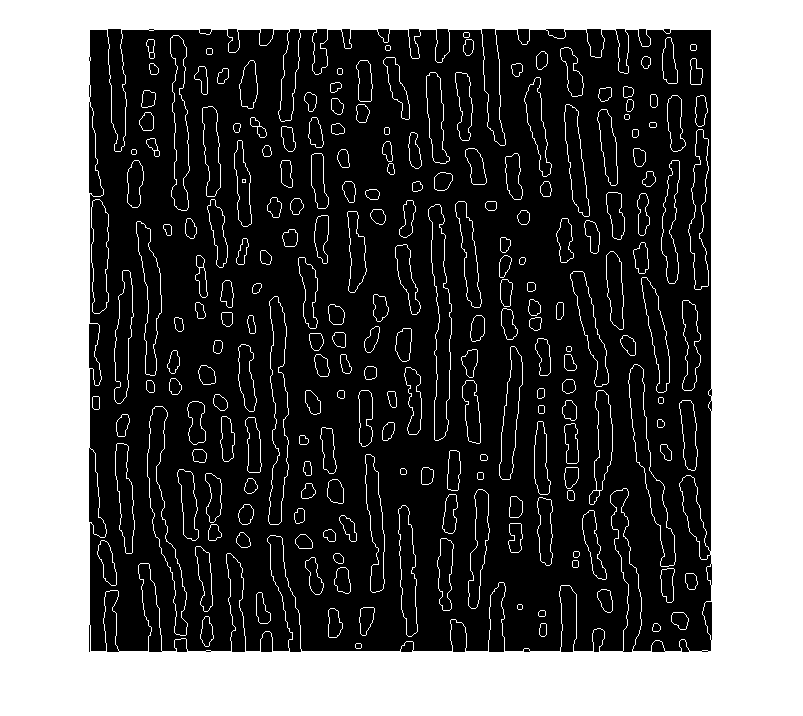

imshow(BW2)

BW2(623,:) = []

BW2 = 622×623 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0

BW2(1,:) = []

BW2 = 621×623 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0

BW2(:,623) = []

BW2 = 621×622 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0

BW2(:,1) = []

BW2 = 621×621 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0

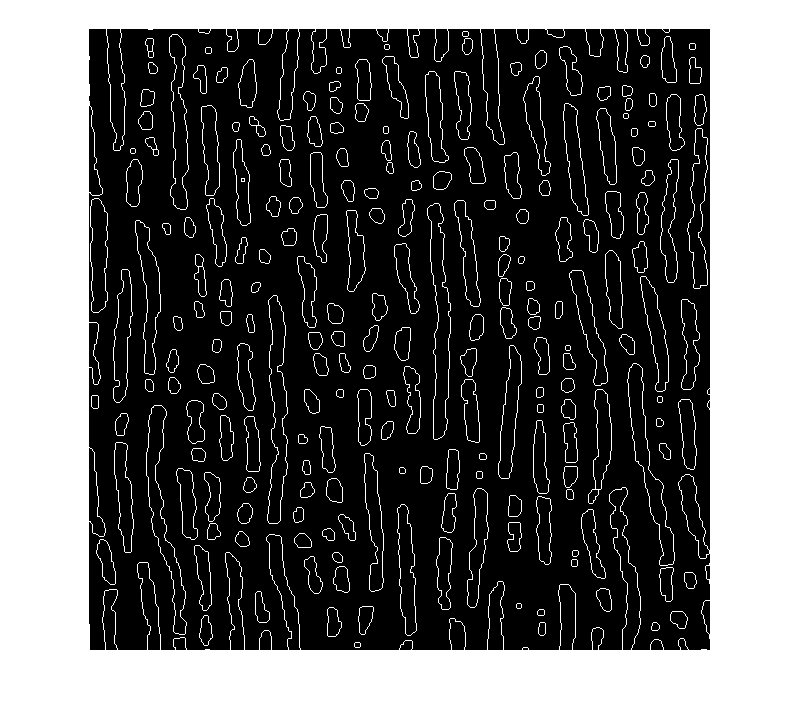

imshow(BW2)

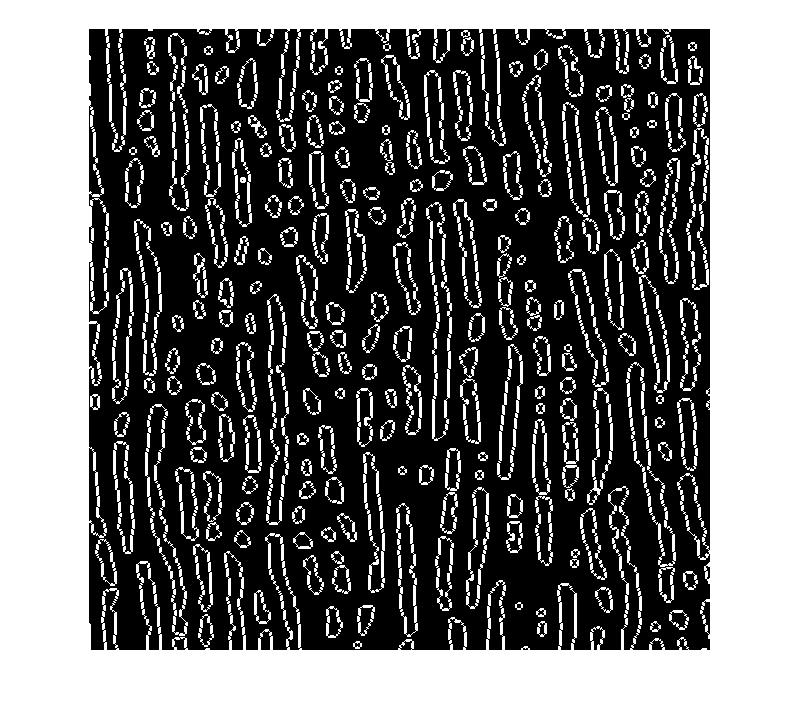

bwmorph(BW2, 'thicken', 1)

J = imcomplement(BW2)

J = 621×621 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1  

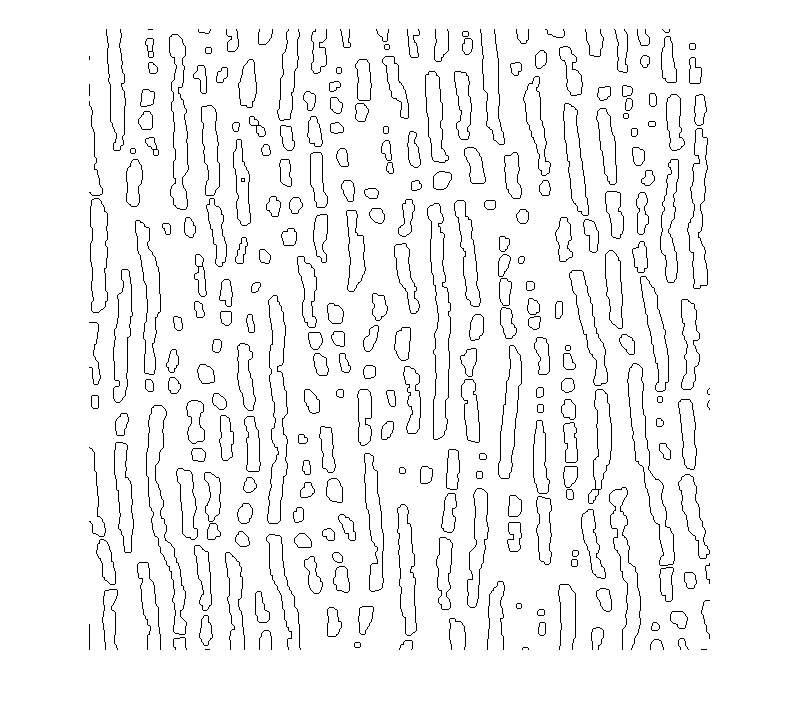

imshow(J)

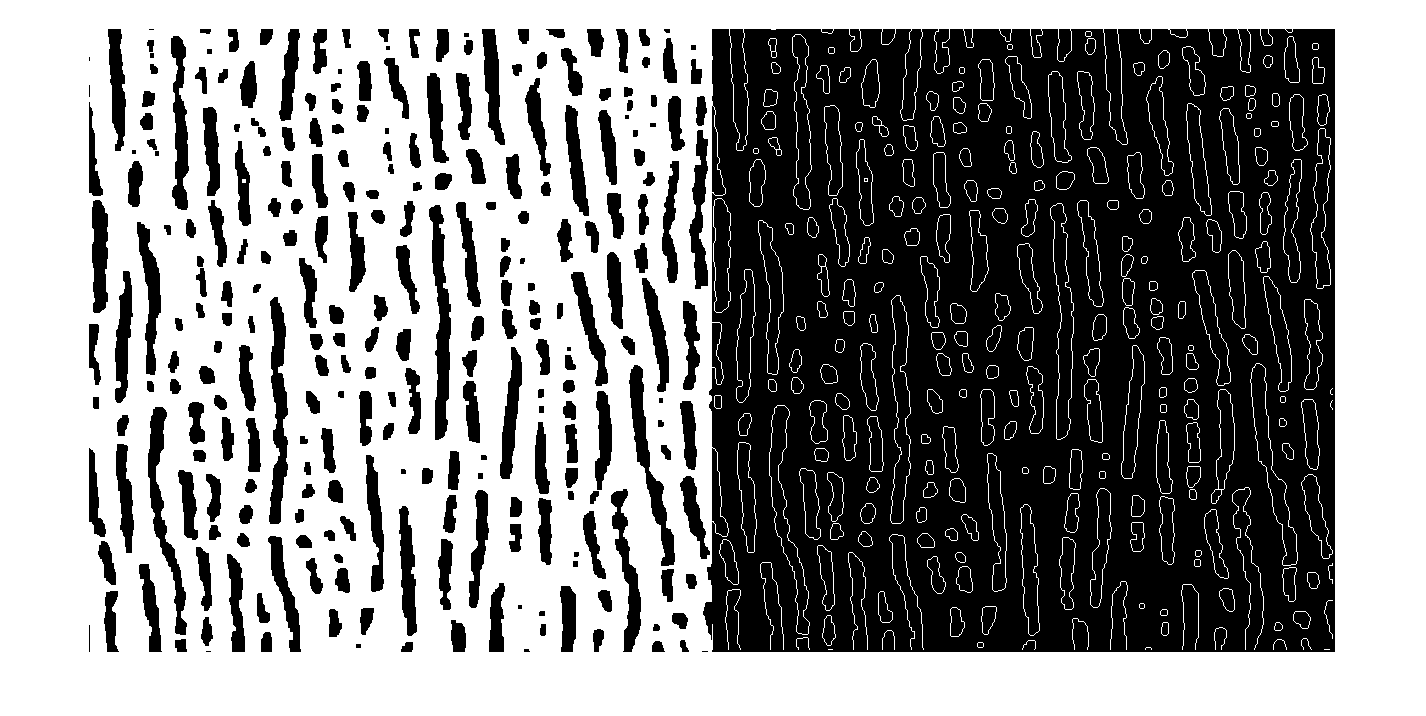

imshowpair(Ieroded,BW2,'montage')

numPerimeterPixels = sum(BW2,"ALL")

numPerimeterPixels = 23159

## Euler Number Calculate

eul=bweuler(Ieroded,8);             %bweuler needs Image Processing Toolbox
fprintf('The Euler Number (O-H) is: %d',eul)  %euler number is Objects - Holes = (O-H) 

The Euler Number (O-H) is: -221

## Normalizing factors

[c r]=size(Ieroded);
f=sum(Ieroded,'all')/(c*r);
fprintf(['The fraction of c/a is: %d'],f);

The fraction of c/a is: 7.403724e-01

N = bwconncomp(Ieroded);           %bwconncomp finds number of objects O 
fprintf(['The Euler Number normalized as (O-H)/(O+H) is: %d'],eul/(2*N.NumObjects-eul));          % (O-H) / [2*O-(O-H)] = (O - H)/(O + H)

The Euler Number normalized as (O-H)/(O+H) is: -9.822222e-01